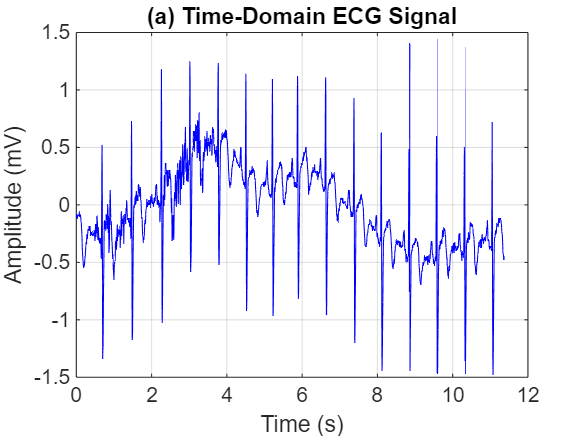

% 學號_姓名：B1110XXXX_張XX
clear; clc; close all;

% 載入 ECG 信號與設定
load wecg;                % wecg, 2048×1
fs = 180;                 % 採樣頻率 180 Hz
ts = 1/fs;                
t = (0:length(wecg)-1)*ts;  % 時間軸 (秒)

figure;
plot(t, wecg, 'b');
xlabel('Time (s)'); ylabel('Amplitude (mV)');
title('(a) Time-Domain ECG Signal');
grid on;

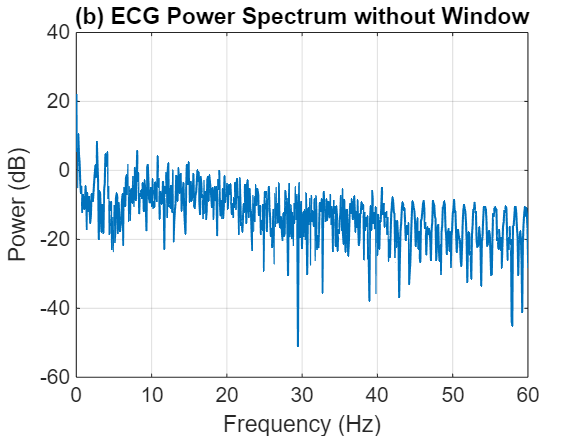



N = length(wecg);
nfft = 2^nextpow2(N);
X = fft(wecg, nfft);
P2 = abs(X).^2 / N;              
P1 = P2(1:nfft/2+1);             
P1(2:end-1) = 2*P1(2:end-1);     

f = fs*(0:(nfft/2))/nfft;        

figure;
plot(f, 10*log10(P1),'LineWidth',1);
xlabel('Frequency (Hz)'); ylabel('Power (dB)');
title('(b) ECG Power Spectrum without Window');
xlim([0 60]);
grid on;

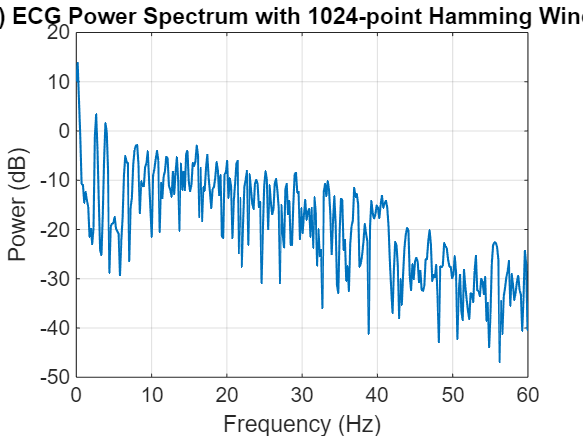



M = 1024;
x_trunc = wecg(1:M);         % 擷取前 1024 樣本
w = hamming(M);
xw = x_trunc .* w;

nfft2 = 2^nextpow2(M);
Xw = fft(xw, nfft2);
P2w = abs(Xw).^2 / M;
P1w = P2w(1:nfft2/2+1);
P1w(2:end-1) = 2*P1w(2:end-1);

fw = fs*(0:(nfft2/2))/nfft2;

figure;
plot(fw, 10*log10(P1w),'LineWidth',1);
xlabel('Frequency (Hz)'); ylabel('Power (dB)');
title('(c) ECG Power Spectrum with 1024-point Hamming Window');
xlim([0 60]);
grid on;


% 假設 Lab7 得到的平均 RR 間期：
meanRR = 0.599;          
HR_lab7 = 60/meanRR;   

% 從 P1 與 P1w 找主峰 (心跳頻率)
[~, idxb] = max(P1(f>=0.5 & f<=2)); 
f_range = f(f>=0.5 & f<=2);
f_peak_b = f_range(idxb);

[~, idxc] = max(P1w(fw>=0.5 & fw<=2)); 
fw_range = fw(fw>=0.5 & fw<=2);
f_peak_c = fw_range(idxc);

HR_b = f_peak_b * 60;   % bpm
HR_c = f_peak_c * 60;   % bpm

% 顯示比較結果
fprintf('Lab7 平均心率: %.1f bpm\n', HR_lab7);

Lab7 平均心率: 100.2 bpm


fprintf('FFT 不加窗估計心率: %.1f bpm (%.2f Hz)\n', HR_b, f_peak_b);

FFT 不加窗估計心率: 31.6 bpm (0.53 Hz)


fprintf('加窗後 FFT 估計心率: %.1f bpm (%.2f Hz)\n', HR_c, f_peak_c);

加窗後 FFT 估計心率: 31.6 bpm (0.53 Hz)
